# Assignment 2

% Setup
clear
profile on;
tic
rng(10)
addpath('functions')
plotPos = [100 100 800, 400];
% Start parallel pool if not already running
poolobj = gcp('nocreate');
if isempty(poolobj)
    parpool; % Start new pool
end

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 6 workers.


## Question 1.1

% Define sys:
s11.A = [1,-2.438, 1.942,-0.502];
s11.B = [1.446, -0.158, -1.093];
s11.C = [1, 0.5,0.75];
% Check stabilaty:
root = roots(s11.A) % Mag of complex eigs below 1, sys is internaly stable and therfore also BIBO stable.

root =     0.9511
    0.9012
    0.5856


abs(root)

ans =     0.9511
    0.9012
    0.5856


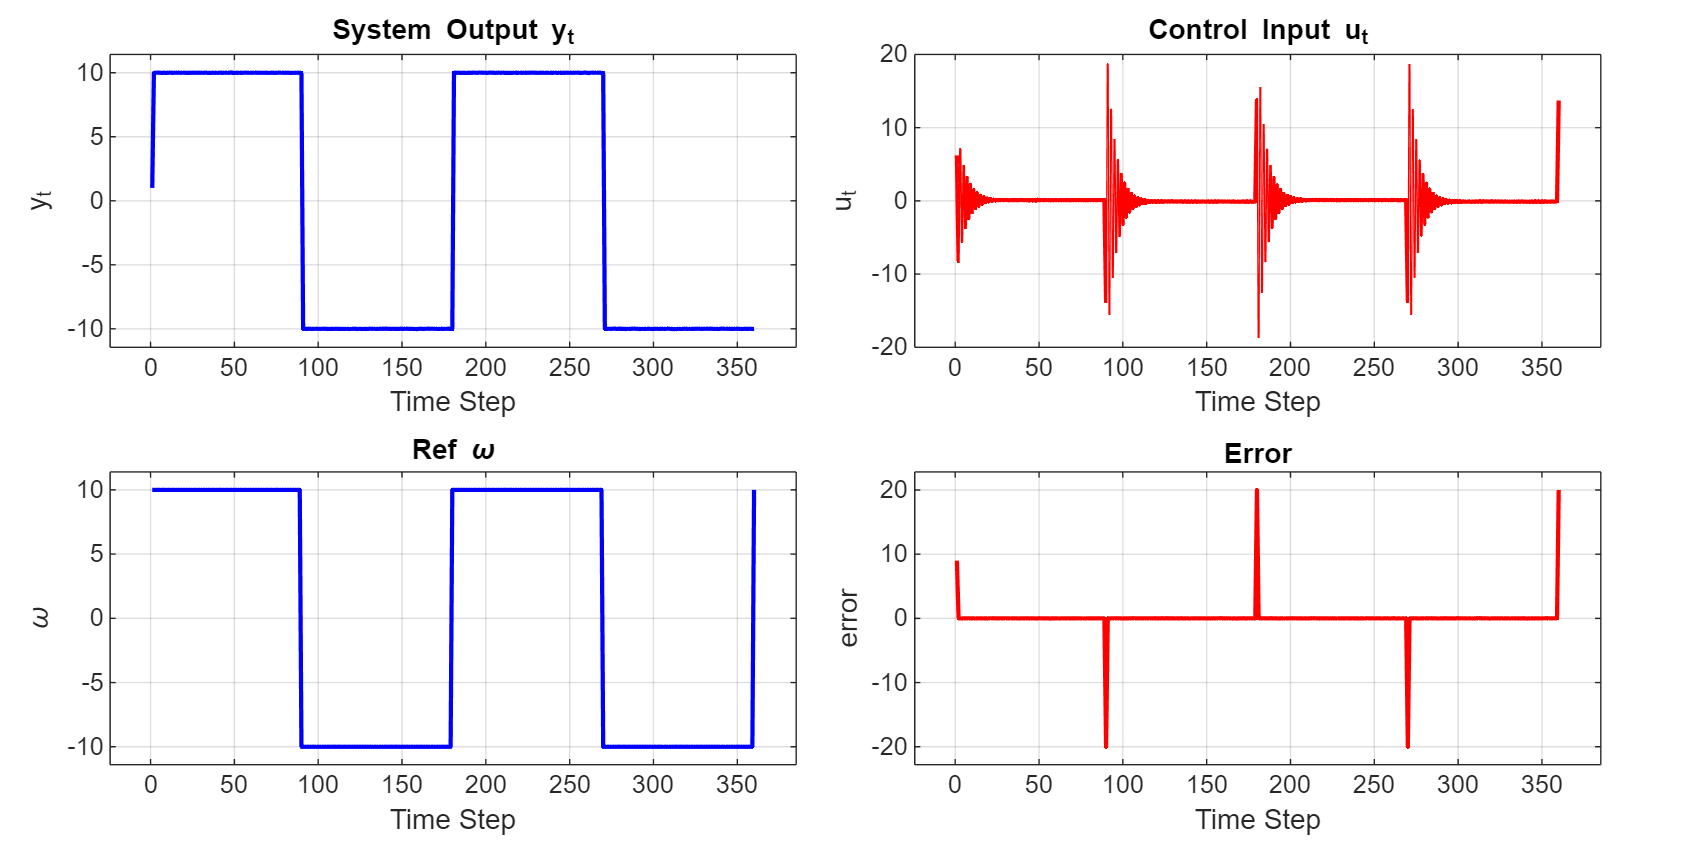

s11.sigma_e = 10^(-2);
s11.N = 360;
s11.k = 1;
n_max = max([length(s11.A),length(s11.B)]);
s11.u_init = zeros(n_max,1);
s11.y_init = ones(n_max,1);

s11.e = normrnd(0, s11.sigma_e,s11.N,1);
T = s11.N/2; % Periode in sampels
s11.omega = 10*square(2*pi*1/T*(1:s11.N),50)';
s11.rho = 0.01;
% [s11.y,s11.u] = MV0(s11.A, s11.B, s11.omega, s11.e, s11.N, s11.k, s11.y_init, s11.u_init);
job1 = parfeval(@MV0, 2, s11.A, s11.B, s11.omega, s11.e, s11.N, s11.k, s11.y_init, s11.u_init);

% wait(job1);
[s11.y, s11.u] = fetchOutputs(job1);

% Define filename
filename = 'MV0.png';

% Call the function with your data structure `s11`
plotSystemResponse(s11, (1:s11.N), plotPos, filename);

## Question 1.2

## Question 1.3

## Question 1.4

## Question 1.5

## Question 2.4

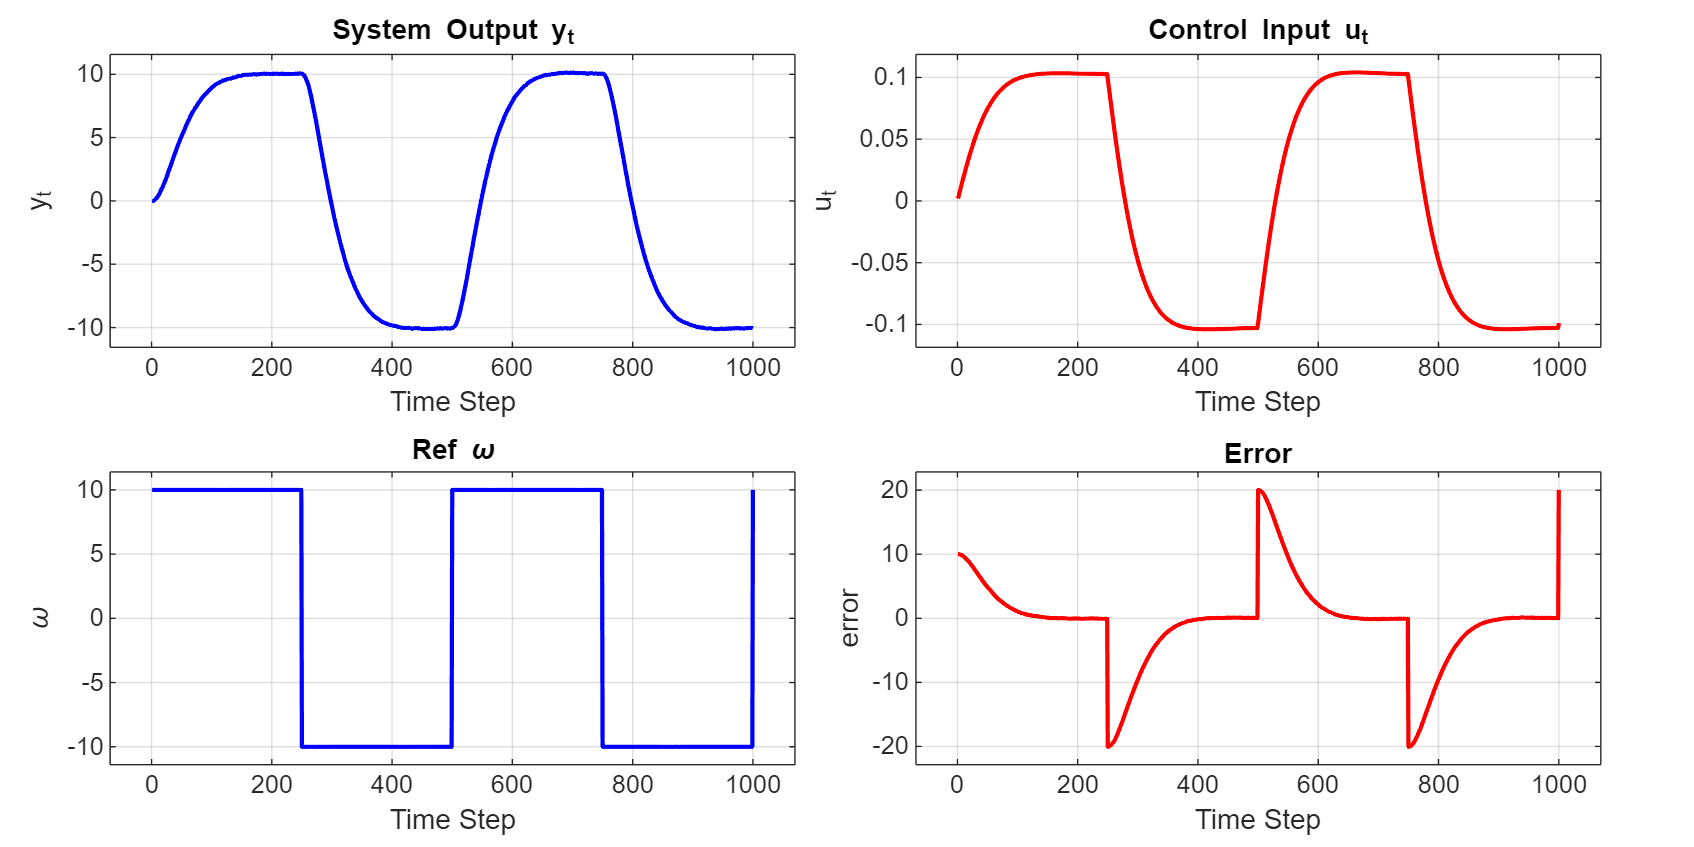

s24.A = [1,-2.438, 1.942,-0.502];
s24.B = [1.446, -0.158, -1.093];
s24.C = [1, -1.441, 0.296, 0.167];
s24.sigma_e = 10^(-2);
s24.N = 1000;
s24.k = 1;
n_max = max([length(s24.A),length(s24.B), length(s24.C)]);



s24.e = normrnd(0, s24.sigma_e,s24.N,1);
T = s24.N/2; % Periode in sampels
s24.omega = 10*square(2*pi*1/T*(1:s24.N),50)';

s24.u_init = 0*ones(n_max,1);
s24.y_init = 0*ones(n_max,1);


Ay = [1];
By = [1]; 
Au = [1]; 
Bu = [1, -1]; % MV1a
Aw = [1]; 
Bw = [1]; 
rho = 7500; % MV1a


% [s24.y,s24.u] = GMV(s24.A, s24.B, s24.C, s24.k, s24.omega,s24.e, s24.N, Ay, By, Au, Bu, Aw, Bw, rho,s24.y_init, s24.u_init);
job2 = parfeval(@GMV, 2, s24.A, s24.B, s24.C, s24.k, s24.omega, s24.e, s24.N, Ay, By, Au, Bu, Aw, Bw, rho, s24.y_init, s24.u_init);






% wait(job2);
[s24.y, s24.u] = fetchOutputs(job2);
% Define filename
filename = 'MV0.png';
s24.omega = filter(Bw,Aw,s24.omega);

% Call the function with your data structure `s11`
plotSystemResponse(s24, (1:s24.N), plotPos, filename);






% Delete jobs to free memory


toc

Elapsed time is 30.126336 seconds.






profile viewer;